# Planteamiento de Cinematica directa

## Definición de las funciones 

Matriz de transformaciones homógeneas

%Deficición de la función de manera simbolica
syms Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j)

%Definición de la transformación homógenea general
Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j) = [cos(ai_j)*cos(bi_j) cos(ai_j)*sin(bi_j)*sin(gi_j)-sin(ai_j)*cos(gi_j) sin(ai_j)*sin(gi_j)+cos(ai_j)*sin(bi_j)*cos(gi_j) x_i_j; sin(ai_j)*cos(bi_j) cos(ai_j)*cos(gi_j)+sin(ai_j)*sin(bi_j)*sin(gi_j) sin(ai_j)*sin(bi_j)*cos(gi_j)-cos(ai_j)*sin(gi_j) y_i_j; -sin(bi_j) cos(bi_j)*sin(gi_j) cos(bi_j)*cos(gi_j) z_i_j; 0 0 0 1]

$$Tij(x\_i\_j, y\_i\_j, z\_i\_j, gi\_j, bi\_j, ai\_j) = \left(\begin{array}{cccc} \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)-\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)+\cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right) & x_{i,j}\\ \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)+\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)-\cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & y_{i,j}\\ -\sin\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right) & z_{i,j}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Ya que tenemos definidos las funciones ahora pasaremos a desarrollar las transformaciones homogeneas de cada eslabon y asi poder obtener la descripcion de  nuestro robot hassta el efector final.

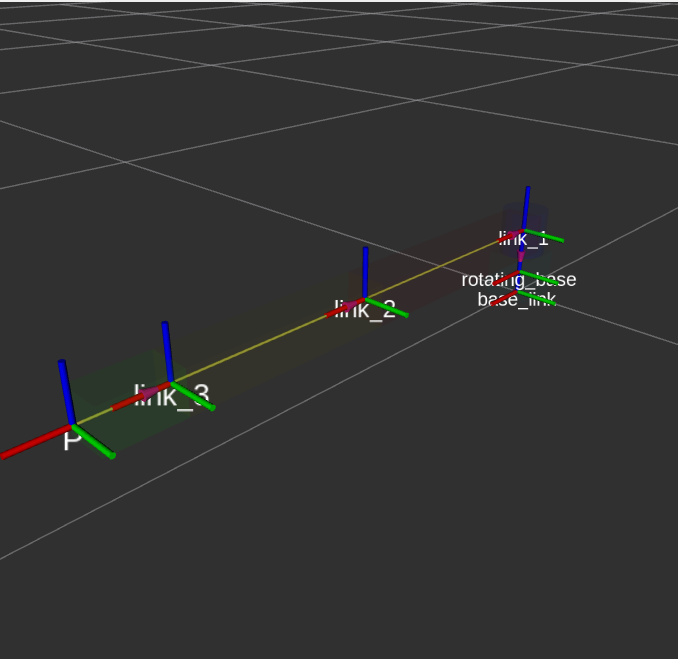

syms T_0_1 z_0_1 theta_0_1 T_1_2 theta_1_2 x_dot_0_1 x_ddot_0_1  z_1_2  pi

T_0_1

$$T\_0\_1 = T_{0,1}$$


T_0_1 = Tij(0,0,z_0_1,0,0,theta_0_1)

$$T\_0\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{0,1}\right) & -\sin\left(\theta_{0,1}\right) & 0 & 0\\ \sin\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right) & 0 & 0\\ 0 & 0 & 1 & z_{0,1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_1_2

$$T\_1\_2 = T_{1,2}$$

T_1_2 = Tij(0,0,z_1_2,0,theta_1_2-pi/2,0)

$$T\_1\_2 = \left(\begin{array}{cccc} \cos\left(\frac{\pi }{2}-\theta_{1,2}\right) & 0 & -\sin\left(\frac{\pi }{2}-\theta_{1,2}\right) & 0\\ 0 & 1 & 0 & 0\\ \sin\left(\frac{\pi }{2}-\theta_{1,2}\right) & 0 & \cos\left(\frac{\pi }{2}-\theta_{1,2}\right) & z_{1,2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

syms T_2_3 x_2_3 theta_2_3 T_3_4 x_3_4 theta_3_4
T_2_3

$$T\_2\_3 = T_{2,3}$$

T_2_3 = Tij(x_2_3,0,0,0,theta_2_3,0)

$$T\_2\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{2,3}\right) & 0 & \sin\left(\theta_{2,3}\right) & x_{2,3}\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{2,3}\right) & 0 & \cos\left(\theta_{2,3}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

f

T_3_4

$$T\_3\_4 = T_{3,4}$$

T_3_4 = Tij(x_3_4,0,0,0,theta_3_4,0)

$$T\_3\_4 = \left(\begin{array}{cccc} \cos\left(\theta_{3,4}\right) & 0 & \sin\left(\theta_{3,4}\right) & x_{3,4}\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{3,4}\right) & 0 & \cos\left(\theta_{3,4}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

syms T_4_P x_4_P
T_4_P

$$T\_4\_P = T_{4,P}$$

T_4_P=Tij(x_4_P,0,0,0,0,0)

$$T\_4\_P = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{4,P}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

El modelo cinemático directo de la posición es:

syms T_0_P

T_0_P = simplify(T_0_1*T_1_2*T_2_3*T_3_4*T_4_P)

$$T\_0\_P = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\theta_{0,1}\right)\,\sigma_{3} & -\sin\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right)\,\sigma_{1} & \cos\left(\theta_{0,1}\right)\,\sigma_{2}\\ \sin\left(\theta_{0,1}\right)\,\sigma_{3} & \cos\left(\theta_{0,1}\right) & \sin\left(\theta_{0,1}\right)\,\sigma_{1} & \sin\left(\theta_{0,1}\right)\,\sigma_{2}\\ -\sigma_{1} & 0 & \sigma_{3} & z_{0,1}+z_{1,2}+x_{2,3}\,\sin\left(\frac{\pi }{2}-\theta_{1,2}\right)-x_{3,4}\,\sin\left(\theta_{1,2}-\frac{\pi }{2}+\theta_{2,3}\right)-x_{4,P}\,\sigma_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1,2}-\frac{\pi }{2}+\theta_{2,3}+\theta_{3,4}\right)\\ \sigma_{2}=x_{2,3}\,\cos\left(\frac{\pi }{2}-\theta_{1,2}\right)+x_{3,4}\,\cos\left(\theta_{1,2}-\frac{\pi }{2}+\theta_{2,3}\right)+x_{4,P}\,\sigma_{3}\\ \sigma_{3}=\cos\left(\theta_{1,2}-\frac{\pi }{2}+\theta_{2,3}+\theta_{3,4}\right) \end{array}$$

Ahora podemos obtener el vector de Postura de nuestro robot 

xi_O_P = [T_0_P(1,4);T_0_P(2,4);T_0_P(3,4);T_0_P(1,1);T_0_P(2,2);T_0_P(3,3)]

$$xi\_O\_P = \begin{array}{l} \left(\begin{array}{c} \cos\left(\theta_{0,1}\right)\,\sigma_{1}\\ \sin\left(\theta_{0,1}\right)\,\sigma_{1}\\ z_{0,1}+z_{1,2}+x_{2,3}\,\sin\left(\frac{\pi }{2}-\theta_{1,2}\right)-x_{3,4}\,\sin\left(\theta_{1,2}-\frac{\pi }{2}+\theta_{2,3}\right)-x_{4,P}\,\sin\left(\theta_{1,2}-\frac{\pi }{2}+\theta_{2,3}+\theta_{3,4}\right)\\ \cos\left(\theta_{0,1}\right)\,\cos\left(\theta_{1,2}-\frac{\pi }{2}+\theta_{2,3}+\theta_{3,4}\right)\\ \cos\left(\theta_{0,1}\right)\\ \cos\left(\theta_{1,2}-\frac{\pi }{2}+\theta_{2,3}+\theta_{3,4}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=x_{2,3}\,\cos\left(\frac{\pi }{2}-\theta_{1,2}\right)+x_{3,4}\,\cos\left(\theta_{1,2}-\frac{\pi }{2}+\theta_{2,3}\right)+x_{4,P}\,\cos\left(\theta_{1,2}-\frac{\pi }{2}+\theta_{2,3}+\theta_{3,4}\right) \end{array}$$

Ya que tenemos la postura, podemos realizar el jacobiano de nuestro robot

J_theta = jacobian(xi_O_P,[theta_0_1,theta_1_2,theta_2_3,theta_3_4])

$$J\_theta = \begin{array}{l} \left(\begin{array}{cccc} -\sin\left(\theta_{0,1}\right)\,\sigma_{3} & -\cos\left(\theta_{0,1}\right)\,\sigma_{1} & -\cos\left(\theta_{0,1}\right)\,\sigma_{4} & -x_{4,P}\,\cos\left(\theta_{0,1}\right)\,\sin\left(\sigma_{6}\right)\\ \cos\left(\theta_{0,1}\right)\,\sigma_{3} & -\sin\left(\theta_{0,1}\right)\,\sigma_{1} & -\sin\left(\theta_{0,1}\right)\,\sigma_{4} & -x_{4,P}\,\sin\left(\theta_{0,1}\right)\,\sin\left(\sigma_{6}\right)\\ 0 & -\sigma_{5}-x_{3,4}\,\cos\left(\sigma_{7}\right)-x_{4,P}\,\cos\left(\sigma_{6}\right) & -x_{3,4}\,\cos\left(\sigma_{7}\right)-x_{4,P}\,\cos\left(\sigma_{6}\right) & -x_{4,P}\,\cos\left(\sigma_{6}\right)\\ -\sin\left(\theta_{0,1}\right)\,\cos\left(\sigma_{6}\right) & \sigma_{2} & \sigma_{2} & \sigma_{2}\\ -\sin\left(\theta_{0,1}\right) & 0 & 0 & 0\\ 0 & -\sin\left(\sigma_{6}\right) & -\sin\left(\sigma_{6}\right) & -\sin\left(\sigma_{6}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=x_{3,4}\,\sin\left(\sigma_{7}\right)-x_{2,3}\,\sin\left(\frac{\pi }{2}-\theta_{1,2}\right)+x_{4,P}\,\sin\left(\sigma_{6}\right)\\ \sigma_{2}=-\cos\left(\theta_{0,1}\right)\,\sin\left(\sigma_{6}\right)\\ \sigma_{3}=\sigma_{5}+x_{3,4}\,\cos\left(\sigma_{7}\right)+x_{4,P}\,\cos\left(\sigma_{6}\right)\\ \sigma_{4}=x_{3,4}\,\sin\left(\sigma_{7}\right)+x_{4,P}\,\sin\left(\sigma_{6}\right)\\ \sigma_{5}=x_{2,3}\,\cos\left(\frac{\pi }{2}-\theta_{1,2}\right)\\ \sigma_{6}=\theta_{1,2}-\frac{\pi }{2}+\theta_{2,3}+\theta_{3,4}\\ \sigma_{7}=\theta_{1,2}-\frac{\pi }{2}+\theta_{2,3} \end{array}$$

Ya que tenemos el jacobiano podemos dar el modelo cinematico directo de la velocidad

syms xi_dot_0_P theta_dot_0_1 theta_dot_1_2 theta_dot_2_3 theta_dot_3_4 q_dot
q_dot

$$q\_dot = \dot{q}$$

q_dot=[theta_dot_0_1;theta_dot_1_2;theta_dot_2_3;theta_dot_3_4 ]

$$q\_dot = \left(\begin{array}{c} {\dot{\theta }}_{0,1}\\ {\dot{\theta }}_{1,2}\\ {\dot{\theta }}_{2,3}\\ {\dot{\theta }}_{3,4} \end{array}\right)$$

xi_dot_0_P

$$xi\_dot\_0\_P = {\dot{\xi }}_{0,P}$$

xi_dot_0_P=J_theta*q_dot

$$xi\_dot\_0\_P = \begin{array}{l} \left(\begin{array}{c} -{\dot{\theta }}_{2,3}\,\cos\left(\theta_{0,1}\right)\,\sigma_{3}-{\dot{\theta }}_{0,1}\,\sin\left(\theta_{0,1}\right)\,\sigma_{1}-{\dot{\theta }}_{1,2}\,\cos\left(\theta_{0,1}\right)\,\sigma_{2}-{\dot{\theta }}_{3,4}\,x_{4,P}\,\cos\left(\theta_{0,1}\right)\,\sin\left(\sigma_{4}\right)\\ {\dot{\theta }}_{0,1}\,\cos\left(\theta_{0,1}\right)\,\sigma_{1}-{\dot{\theta }}_{2,3}\,\sin\left(\theta_{0,1}\right)\,\sigma_{3}-{\dot{\theta }}_{1,2}\,\sin\left(\theta_{0,1}\right)\,\sigma_{2}-{\dot{\theta }}_{3,4}\,x_{4,P}\,\sin\left(\theta_{0,1}\right)\,\sin\left(\sigma_{4}\right)\\ -{\dot{\theta }}_{2,3}\,\left(x_{3,4}\,\cos\left(\sigma_{5}\right)+x_{4,P}\,\cos\left(\sigma_{4}\right)\right)-{\dot{\theta }}_{1,2}\,\sigma_{1}-{\dot{\theta }}_{3,4}\,x_{4,P}\,\cos\left(\sigma_{4}\right)\\ -{\dot{\theta }}_{0,1}\,\sin\left(\theta_{0,1}\right)\,\cos\left(\sigma_{4}\right)-{\dot{\theta }}_{1,2}\,\cos\left(\theta_{0,1}\right)\,\sin\left(\sigma_{4}\right)-{\dot{\theta }}_{2,3}\,\cos\left(\theta_{0,1}\right)\,\sin\left(\sigma_{4}\right)-{\dot{\theta }}_{3,4}\,\cos\left(\theta_{0,1}\right)\,\sin\left(\sigma_{4}\right)\\ -{\dot{\theta }}_{0,1}\,\sin\left(\theta_{0,1}\right)\\ -{\dot{\theta }}_{1,2}\,\sin\left(\sigma_{4}\right)-{\dot{\theta }}_{2,3}\,\sin\left(\sigma_{4}\right)-{\dot{\theta }}_{3,4}\,\sin\left(\sigma_{4}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=x_{2,3}\,\cos\left(\frac{\pi }{2}-\theta_{1,2}\right)+x_{3,4}\,\cos\left(\sigma_{5}\right)+x_{4,P}\,\cos\left(\sigma_{4}\right)\\ \sigma_{2}=x_{3,4}\,\sin\left(\sigma_{5}\right)-x_{2,3}\,\sin\left(\frac{\pi }{2}-\theta_{1,2}\right)+x_{4,P}\,\sin\left(\sigma_{4}\right)\\ \sigma_{3}=x_{3,4}\,\sin\left(\sigma_{5}\right)+x_{4,P}\,\sin\left(\sigma_{4}\right)\\ \sigma_{4}=\theta_{1,2}-\frac{\pi }{2}+\theta_{2,3}+\theta_{3,4}\\ \sigma_{5}=\theta_{1,2}-\frac{\pi }{2}+\theta_{2,3} \end{array}$$

Podemos determinar el indice de manipulabilidad, pero hay que resalizar algunos pasos extras para obtener dicho indice

syms JT_theta determinante_JTJ valores_singulares S pseudo_determinante

JT_theta=J_theta' * J_theta

determinante_JTJ = det(JT_theta)

Ya terminamos con la parte de la cinematica directa

# Cinematica Inversa

Para esta parte, vamos a utilizar el desacoplamiento cinematico, dividiendo el problema en 2(posicionamiento y orientacion)

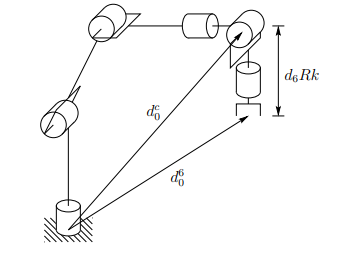

## Posicion

Para esta parte vamos a utilizar las matrices de transformaciones calculadas con anterioridad ,s in embargo modificaremos el T_3_4 para que unicamente saquemos la traslacion de esa transformacion para llegar al centro de la muñeca, ya que la orientacion de esta transformacion se vera para la orientacion del desacoplamiento

syms T_0_4 T_4_Pf T_3_4P

T_0_4

$$T\_0\_4 = T_{0,4}$$

T_3_4P=Tij(x_3_4,0,0,0,0,0);


T_0_4 = simplify(T_0_1*T_1_2*T_2_3*T_3_4P)

$$T\_0\_4 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{3}\,\cos\left(\theta_{0,1}\right) & -\sin\left(\theta_{0,1}\right) & \sigma_{1}\,\cos\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right)\,\sigma_{2}\\ \sigma_{3}\,\sin\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right) & \sigma_{1}\,\sin\left(\theta_{0,1}\right) & \sin\left(\theta_{0,1}\right)\,\sigma_{2}\\ -\sigma_{1} & 0 & \sigma_{3} & z_{0,1}+z_{1,2}+x_{2,3}\,\sin\left(\frac{\pi }{2}-\theta_{1,2}\right)-x_{3,4}\,\sigma_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1,2}-\frac{\pi }{2}+\theta_{2,3}\right)\\ \sigma_{2}=x_{2,3}\,\cos\left(\frac{\pi }{2}-\theta_{1,2}\right)+x_{3,4}\,\sigma_{3}\\ \sigma_{3}=\cos\left(\theta_{1,2}-\frac{\pi }{2}+\theta_{2,3}\right) \end{array}$$

Ya que tenemos la posicion de la muñeca, podemos obtener las formulas para los primeros grados de libertad


$$\left(\begin{array}{c}
x_{0,P} -x_{4,P} \,\cos \left(\alpha_{0,P} \right)\,\sin \left(\beta_{0,P} \right)\\
y_{0,P} -x_{4,P} \,\sin \left(\alpha_{0,P} \right)\,\sin \left(\beta_{0,P} \right)\\
z_{0,P} -x_{4,P} \,\cos \left(\beta_{0,P} \right)\\
1
\end{array}\right)$$


## Orientacion

Debido a la restriccion sobre el giro en X por la configuracion de grados de libertad, la orientacion del efector final depende de todas las orientaciones, pero sobretodo depende de la junsta theta_0_1 y theta_3_4.

Los elementos de orientación del robot están contenidos en la siguiente matriz

T_4_Pf

$$T\_4\_Pf = T_{4,\mathrm{Pf}}$$

syms  T_3_4Or

T_3_4Or=Tij(0,0,0,0, theta_3_4 ,0);

T_4_Pf=simplify(T_3_4Or*T_4_P)

$$T\_4\_Pf = \left(\begin{array}{cccc} \cos\left(\theta_{3,4}\right) & 0 & \sin\left(\theta_{3,4}\right) & x_{4,P}\,\cos\left(\theta_{3,4}\right)\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{3,4}\right) & 0 & \cos\left(\theta_{3,4}\right) & -x_{4,P}\,\sin\left(\theta_{3,4}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Para establecer el desacoplamiento es necesario establecer las matrices de transformación del robot.

Definición de las matrices de rotación

syms R_0_1 R_1_2 R_2_3 R_3_4  R_4_P R_0_3 R_3_Pf
R_0_1 = [T_0_1(1,1),T_0_1(1,2),T_0_1(1,3);T_0_1(2,1),T_0_1(2,2),T_0_1(2,3);T_0_1(3,1),T_0_1(3,2),T_0_1(3,3)]

$$R\_0\_1 = \left(\begin{array}{ccc} \cos\left(\theta_{0,1}\right) & -\sin\left(\theta_{0,1}\right) & 0\\ \sin\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_1_2 = [T_1_2(1,1),T_1_2(1,2),T_1_2(1,3);T_1_2(2,1),T_1_2(2,2),T_1_2(2,3);T_1_2(3,1),T_1_2(3,2),T_1_2(3,3)]

$$R\_1\_2 = \left(\begin{array}{ccc} \cos\left(\frac{\pi }{2}-\theta_{1,2}\right) & 0 & -\sin\left(\frac{\pi }{2}-\theta_{1,2}\right)\\ 0 & 1 & 0\\ \sin\left(\frac{\pi }{2}-\theta_{1,2}\right) & 0 & \cos\left(\frac{\pi }{2}-\theta_{1,2}\right) \end{array}\right)$$

R_2_3 = [T_2_3(1,1),T_2_3(1,2),T_2_3(1,3);T_2_3(2,1),T_2_3(2,2),T_2_3(2,3);T_2_3(3,1),T_2_3(3,2),T_2_3(3,3)]

$$R\_2\_3 = \left(\begin{array}{ccc} \cos\left(\theta_{2,3}\right) & 0 & \sin\left(\theta_{2,3}\right)\\ 0 & 1 & 0\\ -\sin\left(\theta_{2,3}\right) & 0 & \cos\left(\theta_{2,3}\right) \end{array}\right)$$

R_3_4 = [T_3_4(1,1),T_3_4(1,2),T_3_4(1,3);T_3_4(2,1),T_3_4(2,2),T_3_4(2,3);T_3_4(3,1),T_3_4(3,2),T_3_4(3,3)]

$$R\_3\_4 = \left(\begin{array}{ccc} \cos\left(\theta_{3,4}\right) & 0 & \sin\left(\theta_{3,4}\right)\\ 0 & 1 & 0\\ -\sin\left(\theta_{3,4}\right) & 0 & \cos\left(\theta_{3,4}\right) \end{array}\right)$$

R_4_P = [T_4_P(1,1),T_4_P(1,2),T_4_P(1,3);T_4_P(2,1),T_4_P(2,2),T_4_P(2,3);T_4_P(3,1),T_4_P(3,2),T_4_P(3,3)]

$$R\_4\_P = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_0_4 = simplify(R_0_1*R_1_2*R_2_3)

$$R\_0\_4 = \left(\begin{array}{ccc} \cos\left(\theta_{1,2}-\frac{\pi }{2}+\theta_{2,3}\right)\,\cos\left(\theta_{0,1}\right) & -\sin\left(\theta_{0,1}\right) & \sin\left(\theta_{1,2}-\frac{\pi }{2}+\theta_{2,3}\right)\,\cos\left(\theta_{0,1}\right)\\ \cos\left(\theta_{1,2}-\frac{\pi }{2}+\theta_{2,3}\right)\,\sin\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right) & \sin\left(\theta_{1,2}-\frac{\pi }{2}+\theta_{2,3}\right)\,\sin\left(\theta_{0,1}\right)\\ -\sin\left(\theta_{1,2}-\frac{\pi }{2}+\theta_{2,3}\right) & 0 & \cos\left(\theta_{1,2}-\frac{\pi }{2}+\theta_{2,3}\right) \end{array}\right)$$


R_4_Pf = simplify(R_3_4*R_4_P)

$$R\_4\_Pf = \left(\begin{array}{ccc} \cos\left(\theta_{3,4}\right) & 0 & \sin\left(\theta_{3,4}\right)\\ 0 & 1 & 0\\ -\sin\left(\theta_{3,4}\right) & 0 & \cos\left(\theta_{3,4}\right) \end{array}\right)$$

### Planteamiento del desacoplamiento de la orientación del efector final

La orientación del efector final del robot estada por la matriz de rotación ${}^0{\mathbf{R}}_P$ la cual se calcula de la siguiente manera:


$${}^0{\mathbf{R}}_P={}^0{\mathbf{R}}_4{}^4{\mathbf{R}}_P={\mathbf{R}}_T$$


Donde la matriz ${}^0{\mathbf{R}}_4$está relacionada con los tres primeros grados de libertad del robot, y la matriz ${}^4{\mathbf{R}}_P$ esta relacionada directamente con la matriz de orientacion  del codo del robot, y la matriz ${\mathbf{R}}_T$ describe al efector final del robot variables del espacio de trabajo. De la ecuación anterior se puede plantear la ubicación del sistema {4}


$${}^4{\mathbf{R}}_P={}^0{\mathbf{R}}^{-1}_4{\mathbf{R}}_T$$


syms R_4_P_esp x_0_P y_0_P z_0_P beta_0_P alpha_0_P T_T

T_T = Tij(x_0_P,y_0_P,z_0_P,0,beta_0_P,alpha_0_P)

$$T\_T = \left(\begin{array}{cccc} \cos\left(\alpha_{0,P}\right)\,\cos\left(\beta_{0,P}\right) & -\sin\left(\alpha_{0,P}\right) & \cos\left(\alpha_{0,P}\right)\,\sin\left(\beta_{0,P}\right) & x_{0,P}\\ \cos\left(\beta_{0,P}\right)\,\sin\left(\alpha_{0,P}\right) & \cos\left(\alpha_{0,P}\right) & \sin\left(\alpha_{0,P}\right)\,\sin\left(\beta_{0,P}\right) & y_{0,P}\\ -\sin\left(\beta_{0,P}\right) & 0 & \cos\left(\beta_{0,P}\right) & z_{0,P}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

R_T = [T_T(1,1),T_T(1,2),T_T(1,3);T_T(2,1),T_T(2,2),T_T(2,3);T_T(3,1),T_T(3,2),T_T(3,3)]

$$R\_T = \left(\begin{array}{ccc} \cos\left(\alpha_{0,P}\right)\,\cos\left(\beta_{0,P}\right) & -\sin\left(\alpha_{0,P}\right) & \cos\left(\alpha_{0,P}\right)\,\sin\left(\beta_{0,P}\right)\\ \cos\left(\beta_{0,P}\right)\,\sin\left(\alpha_{0,P}\right) & \cos\left(\alpha_{0,P}\right) & \sin\left(\alpha_{0,P}\right)\,\sin\left(\beta_{0,P}\right)\\ -\sin\left(\beta_{0,P}\right) & 0 & \cos\left(\beta_{0,P}\right) \end{array}\right)$$

Con eso podemos determinar la orientacion necesaria para satisfacer la orientacion del efecto final y obtener la posicion de la muñeca

syms d_ef P_wrist
d_ef=[0;0;-x_4_P;1]

$$d\_ef = \left(\begin{array}{c} 0\\ 0\\ -x_{4,P}\\ 1 \end{array}\right)$$

P_wrist=T_T*d_ef

$$P\_wrist = \left(\begin{array}{c} x_{0,P}-x_{4,P}\,\cos\left(\alpha_{0,P}\right)\,\sin\left(\beta_{0,P}\right)\\ y_{0,P}-x_{4,P}\,\sin\left(\alpha_{0,P}\right)\,\sin\left(\beta_{0,P}\right)\\ z_{0,P}-x_{4,P}\,\cos\left(\beta_{0,P}\right)\\ 1 \end{array}\right)$$

Ya obtuvimos la posicion de la muñeca, ya podemos resolver el posicionamiento

Para la orientacion, debido a nuestra configuracion, tenemos restricciones en la orientacion, por lo tanto lo resolveremos asi

Utilizaremos la inversa de la rotacion del tercer eslabon para describir  cómo rotan las articulaciones del brazo para pasar de la orientación actual (R03R_{0_3}R03��) a la orientación deseada (RTR_TRT�) y asi conseguir el angulo para dar la orientacion deseada.

syms R_wrist R_mu R_muneca
R_wrist=simplify(inv(R_0_4)*R_T)

$$R\_wrist = \begin{array}{l} \left(\begin{array}{ccc} \sin\left(\sigma_{1}\right)\,\sin\left(\beta_{0,P}\right)+\cos\left(\sigma_{1}\right)\,\cos\left(\alpha_{0,P}\right)\,\cos\left(\beta_{0,P}\right)\,\cos\left(\theta_{0,1}\right)+\cos\left(\sigma_{1}\right)\,\cos\left(\beta_{0,P}\right)\,\sin\left(\alpha_{0,P}\right)\,\sin\left(\theta_{0,1}\right) & -\sin\left(\alpha_{0,P}-\theta_{0,1}\right)\,\cos\left(\sigma_{1}\right) & \cos\left(\sigma_{1}\right)\,\cos\left(\alpha_{0,P}\right)\,\sin\left(\beta_{0,P}\right)\,\cos\left(\theta_{0,1}\right)-\sin\left(\sigma_{1}\right)\,\cos\left(\beta_{0,P}\right)+\cos\left(\sigma_{1}\right)\,\sin\left(\alpha_{0,P}\right)\,\sin\left(\beta_{0,P}\right)\,\sin\left(\theta_{0,1}\right)\\ \sin\left(\alpha_{0,P}-\theta_{0,1}\right)\,\cos\left(\beta_{0,P}\right) & \cos\left(\alpha_{0,P}-\theta_{0,1}\right) & \sin\left(\alpha_{0,P}-\theta_{0,1}\right)\,\sin\left(\beta_{0,P}\right)\\ \sin\left(\sigma_{1}\right)\,\cos\left(\alpha_{0,P}\right)\,\cos\left(\beta_{0,P}\right)\,\cos\left(\theta_{0,1}\right)-\cos\left(\sigma_{1}\right)\,\sin\left(\beta_{0,P}\right)+\sin\left(\sigma_{1}\right)\,\cos\left(\beta_{0,P}\right)\,\sin\left(\alpha_{0,P}\right)\,\sin\left(\theta_{0,1}\right) & -\sin\left(\alpha_{0,P}-\theta_{0,1}\right)\,\sin\left(\sigma_{1}\right) & \cos\left(\sigma_{1}\right)\,\cos\left(\beta_{0,P}\right)+\sin\left(\sigma_{1}\right)\,\cos\left(\alpha_{0,P}\right)\,\sin\left(\beta_{0,P}\right)\,\cos\left(\theta_{0,1}\right)+\sin\left(\sigma_{1}\right)\,\sin\left(\alpha_{0,P}\right)\,\sin\left(\beta_{0,P}\right)\,\sin\left(\theta_{0,1}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\theta_{1,2}-\frac{\pi }{2}+\theta_{2,3} \end{array}$$

R_mu=subs(R_wrist,[alpha_0_P],[theta_0_1])

$$R\_mu = \begin{array}{l} \left(\begin{array}{ccc} \cos\left(\sigma_{1}\right)\,\cos\left(\beta_{0,P}\right)\,{\cos\left(\theta_{0,1}\right)}^{2}+\cos\left(\sigma_{1}\right)\,\cos\left(\beta_{0,P}\right)\,{\sin\left(\theta_{0,1}\right)}^{2}+\sin\left(\sigma_{1}\right)\,\sin\left(\beta_{0,P}\right) & 0 & \cos\left(\sigma_{1}\right)\,\sin\left(\beta_{0,P}\right)\,{\cos\left(\theta_{0,1}\right)}^{2}+\cos\left(\sigma_{1}\right)\,\sin\left(\beta_{0,P}\right)\,{\sin\left(\theta_{0,1}\right)}^{2}-\sin\left(\sigma_{1}\right)\,\cos\left(\beta_{0,P}\right)\\ 0 & 1 & 0\\ \sin\left(\sigma_{1}\right)\,\cos\left(\beta_{0,P}\right)\,{\cos\left(\theta_{0,1}\right)}^{2}+\sin\left(\sigma_{1}\right)\,\cos\left(\beta_{0,P}\right)\,{\sin\left(\theta_{0,1}\right)}^{2}-\cos\left(\sigma_{1}\right)\,\sin\left(\beta_{0,P}\right) & 0 & \sin\left(\sigma_{1}\right)\,\sin\left(\beta_{0,P}\right)\,{\cos\left(\theta_{0,1}\right)}^{2}+\sin\left(\sigma_{1}\right)\,\sin\left(\beta_{0,P}\right)\,{\sin\left(\theta_{0,1}\right)}^{2}+\cos\left(\sigma_{1}\right)\,\cos\left(\beta_{0,P}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\theta_{1,2}-\frac{\pi }{2}+\theta_{2,3} \end{array}$$

R_muneca=simplify(subs(R_mu,[beta_0_P],[theta_3_4]))

$$R\_muneca = \left(\begin{array}{ccc} \cos\left(\frac{\pi }{2}-\theta_{1,2}-\theta_{2,3}+\theta_{3,4}\right) & 0 & \sin\left(\frac{\pi }{2}-\theta_{1,2}-\theta_{2,3}+\theta_{3,4}\right)\\ 0 & 1 & 0\\ -\sin\left(\frac{\pi }{2}-\theta_{1,2}-\theta_{2,3}+\theta_{3,4}\right) & 0 & \cos\left(\frac{\pi }{2}-\theta_{1,2}-\theta_{2,3}+\theta_{3,4}\right) \end{array}\right)$$

syms Sol_Or
Sol_Or=simplify(R_muneca(3, 3))

$$Sol\_Or = \cos\left(\frac{\pi }{2}-\theta_{1,2}-\theta_{2,3}+\theta_{3,4}\right)$$

Ya que tenemos esta ecuacion solamente falta despejar:

syms r_3_3 eq 
eq=acos(r_3_3)-pi/2+ theta_1_2+theta_2_3

$$eq = \theta_{1,2}-\frac{\pi }{2}+\theta_{2,3}+\mathrm{acos}\left(r_{3,3}\right)$$

------------------------------------------------------------------------------